t1 = [7;6;2;8;4.5;4.5;3;9;1];
t2 = [8;3;6;7;5;4;18;2;1];
t3 = [5;8;3;4;2;8;8;6;1];
t4 = [5.5;8;5.5;7;2;3.5;9;3.5;1];
t5 = [8;14;5;6;4;7;3;1;7];
t6 = [7;3;18;8;4;1;2;5;6];
t7 = [-1;2;-3;4;0;-2;-4;1;3];
t8 = [5;9;6;2;4;1;8;7;3];
t9 = [11;-1;3;0;-3;4;-4;-2;12];
t10 = [11;9;12;8;13;4;-9;0;-3];

t = [t1,t2,t3,t4,t5,t6,t7,t8,t9,t10];

players = {'Mark','Seb','Fred H','Ed','Dom','Fred WH','Sam','Joe','Rupert'};
colours = rand(1,3,9);

% plot(1:10,cumsum(t,2))
% legend(players,'Location','northwest')
% xlabel('Innings')
% ylabel('Cumulative score')

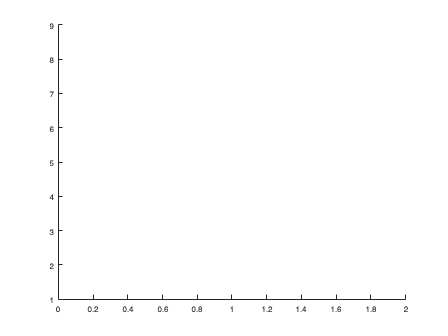

hold off;
cla;
numLines = numel(players);
als = gobjects(1,numLines);
for ii = 1:numLines
    al = animatedline(1,t(ii,1),"Color",colours(:,:,ii));
    % al.DisplayName = players{ii};
    als(ii) = al;
end

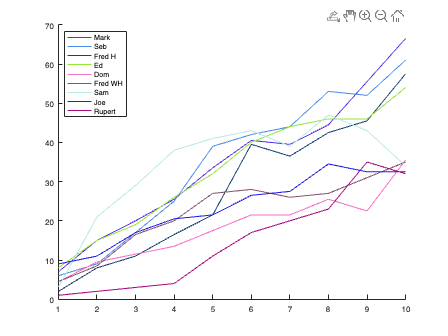

figure(1);
axis([1 10 0 70])
legend(players,"Location","northwest")
for tt = 2:10
    scores = t(:,1:tt);
    for p = 1:numLines
        curLine = als(p);
        addpoints(curLine,tt,sum(scores(p,:)));
    end
    drawnow
end